# Exemple de Live Script sur Matlab

Ce LiveScript est un exemple afin de vous familiariser avec les LiveScript de Matlab. Le principe des LiveScripts est de pouvoir passer du texte au code exécutable d'une ligne à une autre.

Cela permet donc d'écrire des introductions de ce type avant de rentrer dans le vif du sujet sans comprendre l'intérêt d'un fichier Matlab.

Pour structurer le texte, on peut séparer le script en "section" grâce au bouton "Section Break" au-dessus de l'éditeur.

## Trouver les nombres premiers inférieurs à un entier n

Ce script va permettre de trouver les nombres premiers inférieurs à un entier naturel donné.

Soit $n \in \mathbb{N}$, nous souhaitons afficher tous les entiers $p$ tel que $0<p<n$ et p premier.

### Les nombres premiers :

Les nombres premiers sont les briques élémentaires des entiers naturels. En effet, à partir des entiers premiers, on peut créer tous les entiers naturels possible.

#### Définition : Nombre premier 

Soit $p \in \mathbb{N}$. On dit que $p$ est premier si ses diviseurs sont **uniquement** 1 et lui même. 

#### Exemple :

- $p=15=5\times 3$	Les diviseurs de 15 sont donc $\left\lbrace 1,3,5,15\right\rbrace$ et donc p n'est pas premier,

- $p=17$	Les diviseurs de 17 sont $\left\lbrace 1,17\right\rbrace$ donc p est premier.

## Choix de l'entier naturel $n$ :

n = 50;

Ici, on a inséré une ligne de code afin de définir une variable utilisable dans toute la suite du script. On peut donc changer sa valeur à notre guise.

On peut passer du texte au code en cliquant sur le bouton "Code" (uniquement cliquable si le mode texte est activé); et du code au texte en cliquant sur le bouton "Text" (uniquement si le mode code est activé.

### Recherche des entiers premiers inférieurs à $n$:

% Création de tableaux vides qui contiendra les entiers permiers inférieurs
% à n et les entiers non premiers
entierPremier = [];
entierNonPremier = [];

for p = 1:n										% Pour p allant de 1 à n
	
	flag = 1;									% Variable permettant l'arrêt de la boucle si p n'est pas premier
	
	i = 2;										% Variable de test de diviseur
	
	while flag==1									% Tant que le test n'est pas fini
	
		if floor(p/i)==p/i						% Si i est diviseur de p
			flag = -1;							% Alors p n'est pas premier
		else									% Sinon
			i = i+1;							% On incrémente i pour tester un autre diviseur
		end
		
		if i>sqrt(p)							% Si on a atteint i>sqrt(p)
			flag = 0;							% Alors p est premier
		end
		
	end
	
	if flag==0									% Si flag est égal à 0, Alors p est premier
		entierPremier = [entierPremier p];		% Donc on rajoute p dans le tableau des entiers premiers inférieurs à n
	else
		entierNonPremier = [entierNonPremier p];
	end
	
end

On obtient à la fin de cette section de code la liste des entiers premiers dans la variable entierPremier.

### Visualisation des résultats : Affichage des entiers premiers inférieurs à $n$

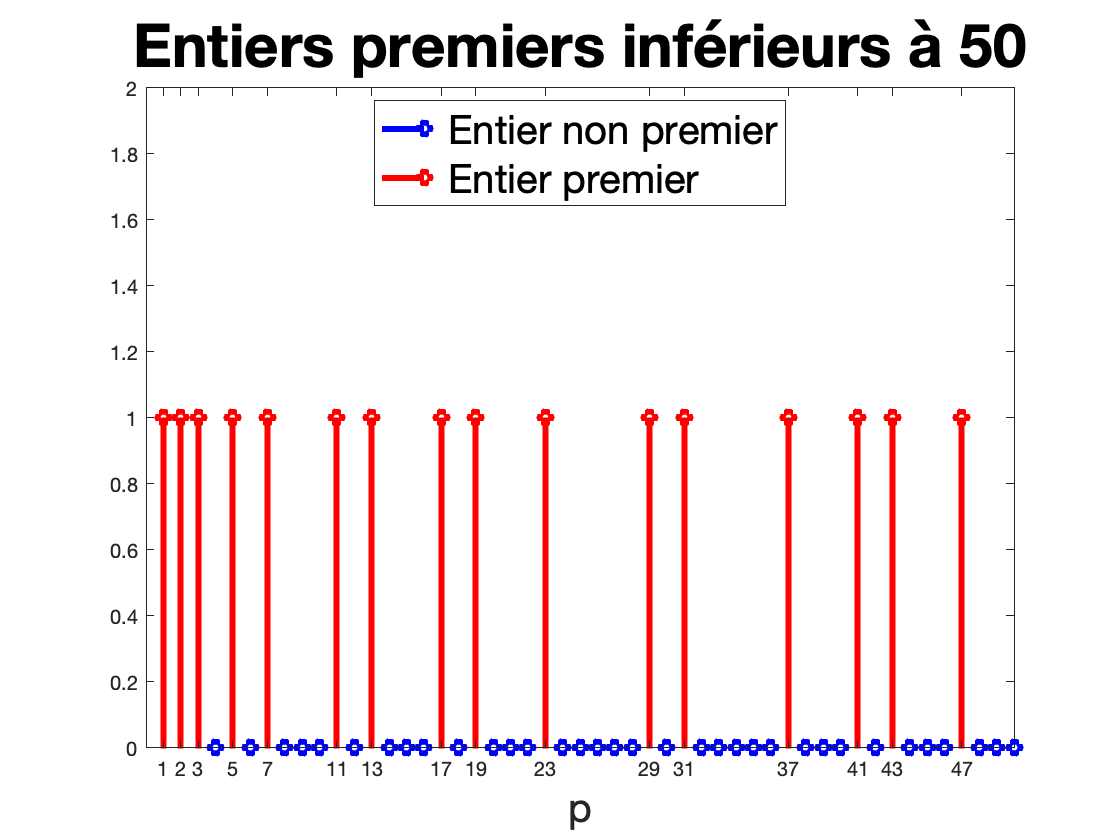

figure,											% Création d'une figure de visualisation
stem(entierNonPremier,zeros(size(entierNonPremier)),'b','LineWidth',3)	% Affichage sur la figure des entiers en bleu
hold on
stem(entierPremier,ones(size(entierPremier)),'r','LineWidth',3)	% Affichage sur la figure des entiers premiers en rouge
xlabel("p",'FontSize',20)						% Affichage de l'abscisse 
title(sprintf("Entiers premiers inférieurs à %d",n),'FontSize',30) % Ajout du titre
xlim([0 n])		% Limitation de l'axe des abscisses
ylim([0 2])	% Limitation de l'axe des ordonnées
legend(["Entier non premier","Entier premier"],'FontSize',20,'Location',"best") % Légende
xticks(entierPremier) % Les abscisses sont formées par les nombres premiers